Esercizio 1:

% parameters value
R1val = sym(10e3); % Ohm
R2val = sym(25e3); % Ohm
C1val = sym(100e-9); % F
C2val = sym(440e-9); % F

% insert your code below this line
%dichiara le variabili
syms R1 R2 C1 C2 Ra Rb A p lambda_A
R1=R1val;
R2=R2val;
C1=C1val;
C2=C2val;
Ra=1/p;
Rb=25/p;
%fai in modo che p sia tra 1/1000 e 1000
assume (1/1000<=p & p<=1000);
%definisci la matrice A (basta vedere i coefficenti che moltiplicano x1 e x2, quindi se x1'=Ax1+Bx2 e x2'=Cx1+Dx2 allora la prima riga della matrice A sarà A, B mentre la seconda sarà C, D)
A=[-(1/(R1*C1)+1/(Ra*C1)), 0; -(Rb/Ra)*(1/R2*C2), -1/(R2*C2)]

$$A = \left(\begin{array}{cc} -10000000\,p-1000 & 0\\ -\frac{519460313115661}{1180591620717411303424000} & -\frac{147573952589676412928}{1623313478486440625} \end{array}\right)$$

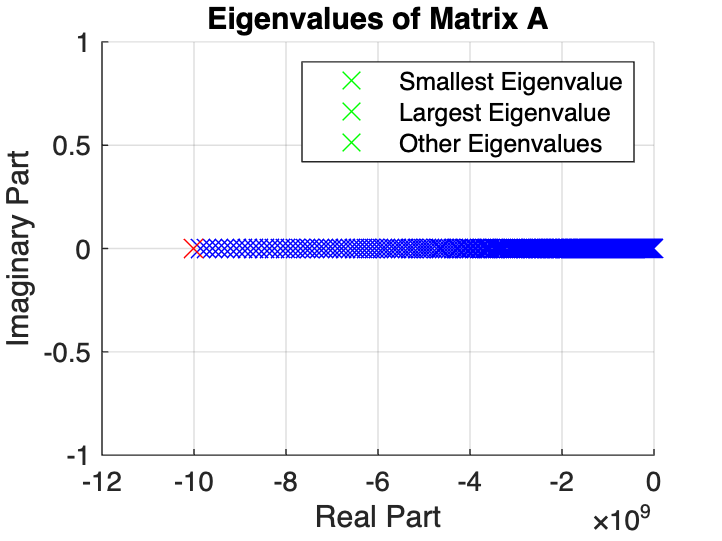

%definisci il vettore lambda con il comando eig(A) che ti da gli autovalori della matrice
lambda_A=eig(A);
%li ordino con il comando che è dato anche dal prof
  sort(lambda_A, 'ascend');
  % creo dei valori per p con questo comando trovato su chatgpt copia incollando la consegna bisogna mettere il nome dell'array=logspace(log10(lower_bound), log10(upper_bound), numero_di_valori_che_si_vuole_generare)
  pVal= logspace(log10(1/1000), log10(1000), 1000);
  % sostituisco i valori appena creati di p all'interno dell'array con gli autovalori e creo una matrice 2*1000 
  eigA_p= subs(lambda_A, p, pVal);
  %creo il grafico con questo pezzo di codice che mi son fatto dare da chatgpt e che non ho capito benissimo come funziona 
% Find the smallest and largest eigenvalues
smallest_eigenvalue = min(eigA_p(:));
largest_eigenvalue = max(eigA_p(:));

% Plot the eigenvalues with different markers based on their value
figure;
hold on;
for i = 1:size(eigA_p, 1)
    for j = 1:size(eigA_p, 2)
        current_eigenvalue = eigA_p(i, j);
        if current_eigenvalue == smallest_eigenvalue
            % Plot the smallest eigenvalue with a red 'x'
            plot(real(current_eigenvalue), imag(current_eigenvalue), 'rx', 'MarkerSize', 10);
        elseif current_eigenvalue == largest_eigenvalue
            % Plot the largest eigenvalue with a green 'x'
            plot(real(current_eigenvalue), imag(current_eigenvalue), 'gx', 'MarkerSize', 10);
        else
            % Plot the remaining eigenvalues with a blue 'x'
            plot(real(current_eigenvalue), imag(current_eigenvalue), 'bx', 'MarkerSize', 10);
        end
    end
end
xlabel('Real Part');
ylabel('Imaginary Part');
title('Eigenvalues of Matrix A');
legend('Smallest Eigenvalue', 'Largest Eigenvalue', 'Other Eigenvalues');
grid on;
hold off;